% source: https://www.kth.se/polopoly_fs/1.588039.1550155544!/Thesis%20KTH%20-%20Francesco%20Sabatino.pdf
% u = [ft; tx; ty; tz];


$$\dot{\mathbf{x}}=\mathbf{A} \cdot \mathbf{x}+\mathbf{B} \cdot \mathbf{u}+\mathbf{D} \cdot \mathbf{d}$$



$$\mathbf{x}=\left[\begin{array}{llllllllllll}
\phi & \theta & \psi & p & q & r & u & v & w & x & y & z
\end{array}\right]^{T} \in \mathbb{R}^{12}$$



$$\mathbf{u}=\left[\begin{array}{llll}
f_{t} & \tau_{x} & \tau_{y} & \tau_{z}
\end{array}\right]^{T} \in \mathbb{R}^{4}$$



$$\left[\begin{array}{lll}
\dot{\phi} & \dot{\theta} & \dot{\psi}
\end{array}\right]^{T}=\left[\begin{array}{lll}
p & q & r
\end{array}\right]^{T}$$



$$\mathbf{y}=\left[\begin{array}{llllll}
 \phi & \theta & \psi & x & y & z  
\end{array}\right]$$



$$\left\{\begin{array}{l}
\dot{\phi}=p \\
\dot{\theta}=q \\
\dot{\psi}=r \\
\dot{p}=\frac{\tau_{x}+\tau_{w x}}{I_{x}} \\
\dot{q}=\frac{\tau_{y}+\tau_{w y}}{I_{y}} \\
\dot{r}=\frac{\tau_{z}+\tau_{w z}}{I_{z}} \\
\dot{u}=-g \theta+\frac{f_{w x}}{m} \\
\dot{v}=g \phi+\frac{f_{w y}}{m} \\
\dot{w}=\frac{f_{w z}-f_{t}}{m} \\
\dot{x}=u \\
\dot{y}=v \\
\dot{z}=w
\end{array}\right.$$


clear all
close all
clc

global A;
global B;
global Bnew;
global u;

g = 9.81;
m = 0.468;
Ix = 4.856e-3;
Iy = 4.856e-3;
Iz = 8.801e-3;

A = [0 0 0 1 0 0 0 0 0 0 0 0;
     0 0 0 0 1 0 0 0 0 0 0 0;
     0 0 0 0 0 1 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 -g 0 0 0 0 0 0 0 0 0 0;
     g 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 1 0 0 0 0;
     0 0 0 0 0 0 0 0 1 0 0 0];
 B = [0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 1/Ix 0 0;
      0 0 1/Iy 0;
      0 0 0 1/Iz;
      0 0 0 0;
      0 0 0 0;
      1/m 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0];
  Bnew = [0;0;0;0;0;0;0;0;1/m;0;0;0];
  C = [1 0 0 0 0 0 0 0 0 0 0 0;
       0 1 0 0 0 0 0 0 0 0 0 0;
       0 0 1 0 0 0 0 0 0 0 0 0;
       0 0 0 0 0 0 0 0 0 1 0 0;
       0 0 0 0 0 0 0 0 0 0 1 0;
       0 0 0 0 0 0 0 0 0 0 0 1];
  D = [0 0 0 0;
       0 0 0 0;
       0 0 0 0;
       0 0 0 0;
       0 0 0 0;
       0 0 0 0];
   
   % disturbance
  E = [0 0 0 0 0 0;
       0 0 0 0 0 0;
       0 0 0 0 0 0;
       0 0 0 1/Ix 0 0;
       0 0 0 0 1/Iy 0;
       0 0 0 0 0 1/Iz;
       1/m 0 0 0 0 0;
       0 1/m 0 0 0 0;
       0 0 1/m 0 0 0;
       0 0 0 0 0 0;
       0 0 0 0 0 0;
       0 0 0 0 0 0];
   
   x0 = zeros(12,1);
   
   sys = ss(A,B,C,D)

sys =
 
  A = 
           x1     x2     x3     x4     x5     x6     x7     x8     x9    x10    x11    x12
   x1       0      0      0      1      0      0      0      0      0      0      0      0
   x2       0      0      0      0      1      0      0      0      0      0      0      0
   x3       0      0      0      0      0      1      0      0      0      0      0      0
   x4       0      0      0      0      0      0      0      0      0      0      0      0
   x5       0      0      0      0      0      0      0      0      0      0      0      0
   x6       0      0      0      0      0      0      0      0      0      0      0      0
   x7       0  -9.81      0      0      0      0      0      0      0      0      0      0
   x8    9.81      0      0      0      0      0      0      0      0      0      0      0
   x9       0      0      0      0      0      0      0      0      0      0      0      0
   x10      0      0      0      0      0      0      1      0      0      

%    t_temp = 0:0.02:10;
%    u_temp = zeros(size(t_temp,2),4)
%    u_temp(:,1) = ones(size(t_temp,2),1)
%    [y,t,xtemp] = lsim(sys,u_temp,t_temp,x0);
%    plot((0:0.02:10),y)
%    legend('1','2','3','4','5','6')

# Timing Parameters

dt = 0.02;
t_total = 30;
t_span = 0:dt:t_total;

% target measurement - pulse
ref_fuc = @(i) 2+2*mod(floor(i*dt/12),2);
ref = zeros(size(t_span,2),1);
for i = 1:length(ref)
    ref(i,1) = ref_fuc(i);
end

# PID Parameters

global windupGuard;
global proportional_gain;
global integral_gain;
global derivative_gain;
global prev_error;
global int_error;
global control;
global control_up;
global control_lo;

% set these as needed
control = 0;
windupGuard = 100;
proportional_gain = 0.1%19.43;0.1

proportional_gain = 0.1000

integral_gain = 0;%0.6142;
derivative_gain = 0.6;%0.08856;0.5
control_up = 50;
control_lo = -50;
 
% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

% call update function
%pid_update(19, 1.0)

# Simulation - No attacks

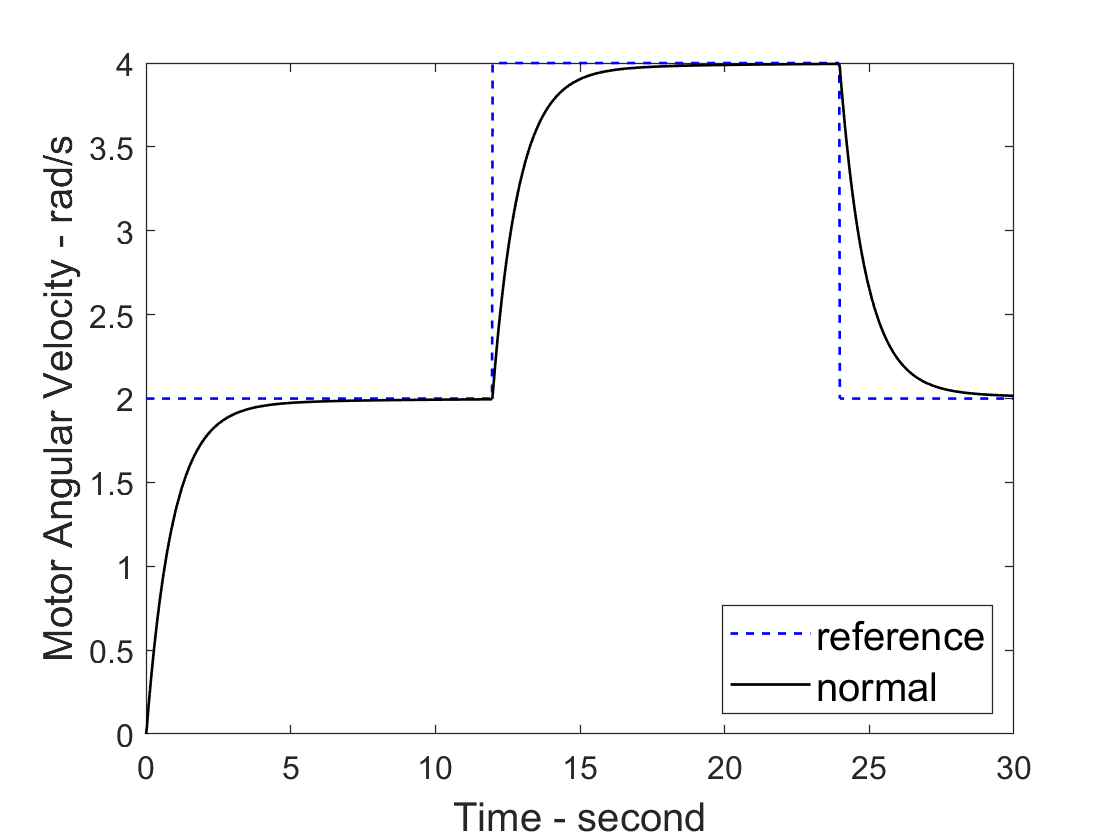

close all

% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;
y = C * x0;

for i = 2:(t_total/dt+1)
    error = ref(i,1) - y(end,end);
    pid_update(error, dt);
    u = [control;0;0;0];
%     [y,t,xtemp] = lsim(sys,control(end,1)*ones(size(0:dt:dt))',(0:dt:dt),xlast);
    [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
    y = C * xtemp(end,:)';
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
end

plot(t_span,ref(:,1),'b--',t_span,x(:,end),'k', 'LineWidth', 1);
set(gca,'FontSize',12)
ylabel('Motor Angular Velocity - rad/s','FontSize',15);
xlabel('Time - second','FontSize',15);
legend('reference','normal','Location','SouthEast','FontSize',15);

# Simulation - Attack, No recovery

% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

t_attack = 6;

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;
% # of measurements
y = zeros(size(t_span,2),1); 
y_all = C * x0;
y_all

y_all =      0
     0
     0
     0
     0
     0


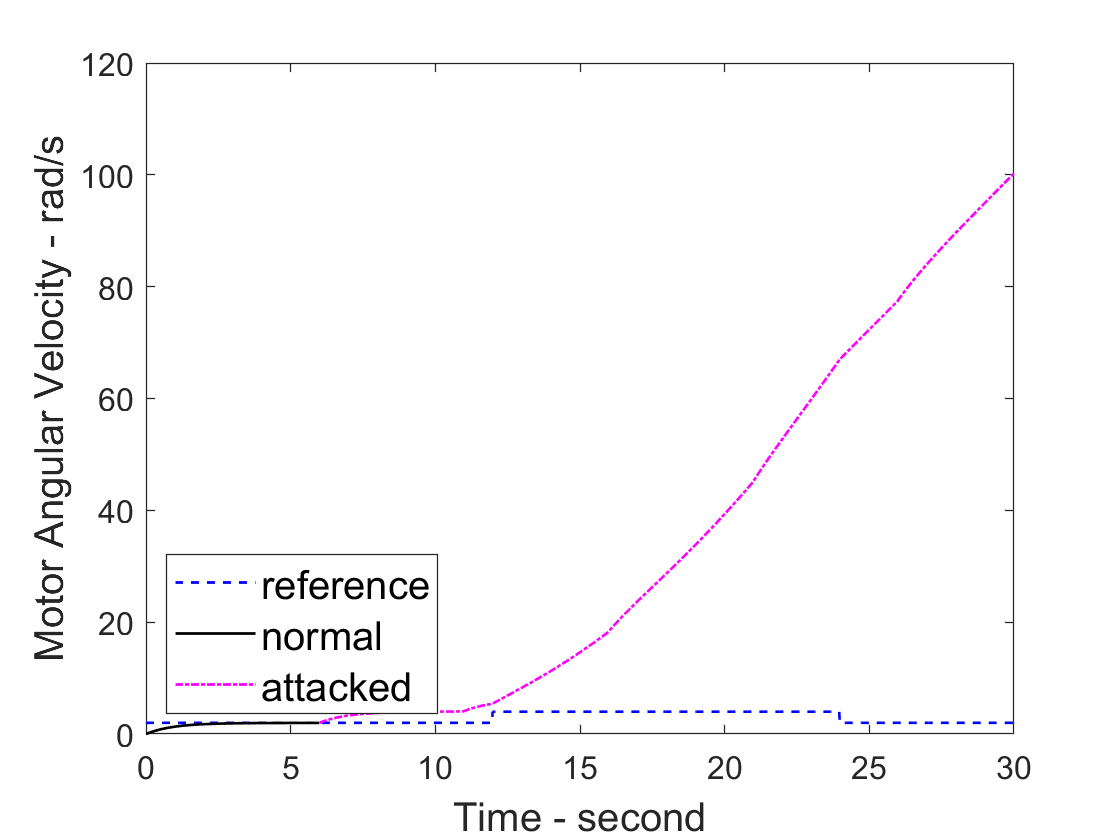

y(1,:) = y_all(end,1);
y_dirty = zeros(size(t_span,2),1);  
y_dirty(1,:) = y_all(end,1);

attack_type = "replay";

% flag
attacked = 0;
last_normal = 0;

for i = 2:(t_total/dt+1)
    if i > t_attack/dt
        if ~attacked
            last_normal = y(i-1,end);
            attacked = 1;
        end
        if strcmp(attack_type,'delay')
            y_dirty(i-1,1) = last_normal;
            delay_step = 50;
            if i-t_attack/dt > delay_step
                y_dirty(i-1,1) = y(i-delay_step,1);
            else
                y_dirty(i-1,1) = last_normal;
            end
        elseif strcmp(attack_type,'alter')
%                 y_dirty(i-1,1) = last_normal + 0.001*(i-t_attack/dt)
            y_dirty(i-1,1) = y(i-1,1) + 2;
        elseif strcmp(attack_type,'replay')
            index = mod(ceil(i-t_attack/dt),ceil(5/dt))+1;
            y_dirty(i-1,1) = y(index,1);
        end
    end
    
    error_dirty = ref(i,1) - y_dirty(i-1,1);
    pid_update(error_dirty, dt);
    u = [control;0;0;0];
    
    %[ytemp,t,xtemp] = lsim(sys,control(end,1)*ones(size(0:dt:dt))',(0:dt:dt),xlast);
    [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
    t_temp_all = C * xtemp(end,:)';
    ytemp = t_temp_all(end,end);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
    y(i,:) = ytemp;
    y_dirty(i,:) = ytemp;
    
end


pa = t_attack/dt;
plot(t_span,ref(:,1),'b--',t_span(1,1:pa),x(1:pa,end),'k', ...
    t_span(1,pa:end),x(pa:end,end),'m-.', 'LineWidth', 1);
set(gca,'FontSize',12)
ylabel('Motor Angular Velocity - rad/s','FontSize',15);
xlabel('Time - second','FontSize',15);
legend('reference','normal','attacked','Location','SouthWest','FontSize',15);

# Simulation - Attack, With recovery

% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

t_attack = 6;
t_detected = 9;
% recovery steps
k = 12;
inputs = zeros(k,1);

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;
% # of measurements
y = zeros(size(t_span,2),1); 
y_all = C * x0;
y(1,:) = y_all(end,1);
y_dirty = zeros(size(t_span,2),1);  
y_dirty(1,:) = y_all(end,1);

attack_type = "replay";

% flag
attacked = 0;
last_normal = 0;
detected = 0;
reset = 0;

figure();

for i = 2:(t_total/dt+1)
    % detection here
    if i == (t_detected)/dt
        detected = 1;
    end
    % end of detection 
    
    if i > t_attack/dt
        if detected
            % recovery here        
            if ~reset
                reset = 1;
                disp('recoverd!');
                [Ad, Bd] = LTI_translation(A,Bnew,dt);
                initial_set_lo = xlast;
                initial_set_up = xlast;
                safe_set_lo = ones(size(x0))*(-10); safe_set_lo(end,1)=0;
                safe_set_up = ones(size(x0))*10; safe_set_up(end,1)=8;
                errorbound = ones(size(x0))*10; errorbound(end,1)=0.1;
                target_set = zeros(size(x0))*10; target_set(end,1)=ref(i,1);
                target_set_lo = target_set - errorbound;
                target_set_up = target_set + errorbound;
                %tic
                utemp = recovery_control(Ad, Bd, k, initial_set_lo, initial_set_up, target_set_lo, target_set_up, safe_set_lo, safe_set_up, control_up, control_lo);
                %timeElapsed = toc
                inputs = utemp((length(utemp)-k+1):end,1);
            end
            % end of recovery 
        else
            if ~attacked
                last_normal = y(i-1,end);
                attacked = 1;
            end
            if strcmp(attack_type,'delay')
                y_dirty(i-1,1) = last_normal;
                delay_step = 50;
                if i-t_attack/dt > delay_step
                    y_dirty(i-1,1) = y(i-delay_step,1);
                else
                    y_dirty(i-1,1) = last_normal;
                end
            elseif strcmp(attack_type,'alter')
    %                 y_dirty(i-1,1) = last_normal + 0.001*(i-t_attack/dt)
                y_dirty(i-1,1) = y(i-1,1) + 2;
            elseif strcmp(attack_type,'replay')
                index = mod(ceil(i-t_attack/dt),ceil(5/dt))+1;
                y_dirty(i-1,1) = y(index,1);
            end
        end
    end
        
    % PID control
    if i<t_detected/dt || i>=t_detected/dt + k
        error_dirty = ref(i,1) - y_dirty(i-1,1);
        pid_update(error_dirty, dt);
    else
        % recovery input
        index = i-t_detected/dt+1
        control = inputs(index,1)
    end
    
    u = [control;0;0;0];
    
    %[ytemp,t,xtemp] = lsim(sys,control(end,1)*ones(size(0:dt:dt))',(0:dt:dt),xlast);
    [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
    t_temp_all = C * xtemp(end,:)';
    ytemp = t_temp_all(end,end);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
    y(i,:) = ytemp;
    y_dirty(i,:) = ytemp;

    if i == t_detected/dt + k - 1
        index = i-t_detected/dt+1
        xlast
    end
    
%     hold on 
%     plot(i*dt,xlast(end,1),'r*');
    
end

recoverd!


initial_set_lo =          0
         0
         0
         0
         0
         0
         0
         0
    0.1073
         0


initial_set_up =          0
         0
         0
         0
         0
         0
         0
         0
    0.1073
         0


target_set_lo =    -10
   -10
   -10
   -10
   -10
   -10
   -10
   -10
   -10
   -10


target_set_up =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10


safe_set_lo =    -10
   -10
   -10
   -10
   -10
   -10
   -10
   -10
   -10
   -10


safe_set_up =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10


control_lo = -50

control_up = 50

Optimal solution found.



result =          0
         0
         0
         0
         0
         0
         0
         0
    0.1073
         0


index = 1

control = -50.0000

index = 2

control = -50.0000

index = 3

control = -50.0000

index = 4

control = -50.0000

index = 5

control = -36.5107

index = 6

control = 0

index = 7

control = 0

index = 8

control = 0

index = 9

control = 0

index = 10

control = 0

index = 11

control = 4.6878e-14

index = 12

control = 0

index = 12

xlast =          0
         0
         0
         0
         0
         0
         0
         0
  -10.0000
         0


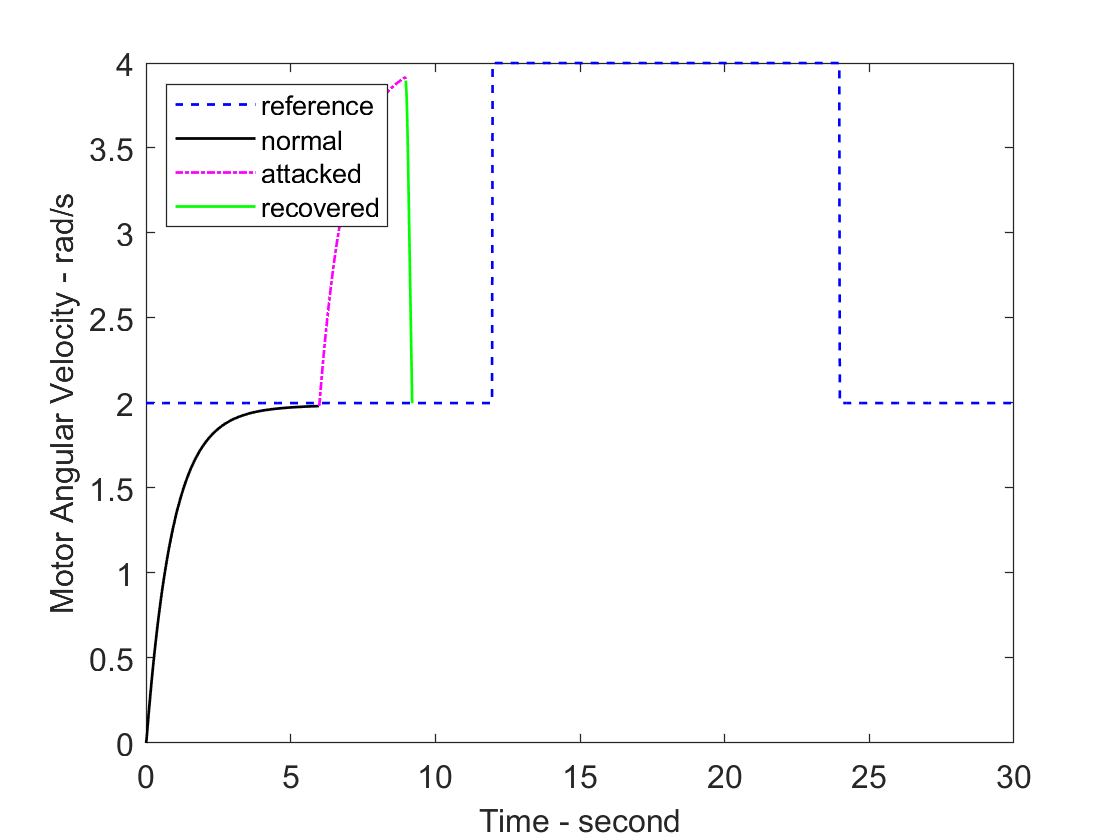


pa = t_attack/dt;
pr = (t_detected)/dt;
pt = t_detected/dt + k - 1;

plot(t_span,ref(:,1),'b--', ...
    t_span(1,1:pa),x(1:pa,end),'k', ...
    t_span(1,pa:pr),x(pa:pr,end),'m-.', ...
    t_span(1,pr:pt),x(pr:pt,end),'g', 'LineWidth', 1);
set(gca,'FontSize',12);
ylabel('Motor Angular Velocity - rad/s','FontSize',12);
xlabel('Time - second','FontSize',12);
legend('reference','normal','attacked','recovered','Location','NorthWest','FontSize',10);

function dxdt = dynamics(t, x)

global A;
global B;
global u;

dxdt = A*x + B*u;

end